clear
% if ~exist("sat1","var")
    sat1 = import_state("sat1.txt")

sat1 = 10001×14 table
    time           x                   y            z             vx                    vy           vz           q1                     q2                     q3                    q4                   om1                  om2            om3
    ____    ________________    ________________    _    ____________________    ________________    __    _________________    ____________________    ___________________    _________________    _________________    __________________    ___

      0        

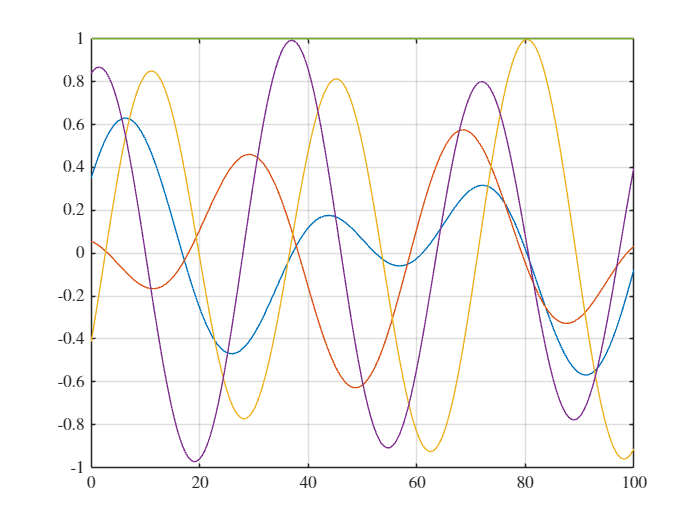

% end

figure()
plot(sat1.time,sat1.q1)
hold on
plot(sat1.time,sat1.q2)
plot(sat1.time,sat1.q3)
plot(sat1.time,sat1.q4)
qnorm = vecnorm([sat1.q1,sat1.q2,sat1.q3,sat1.q4],2,2);
plot(sat1.time,qnorm)
grid on
xlim([0,100])
hold off

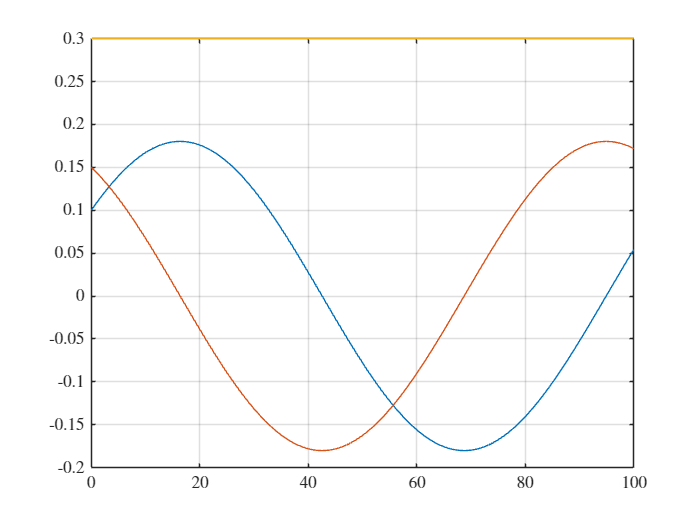


figure()
plot(sat1.time,sat1.om1)
hold on
plot(sat1.time,sat1.om2)
plot(sat1.time,sat1.om3)
grid on
xlim([0,100])
hold off

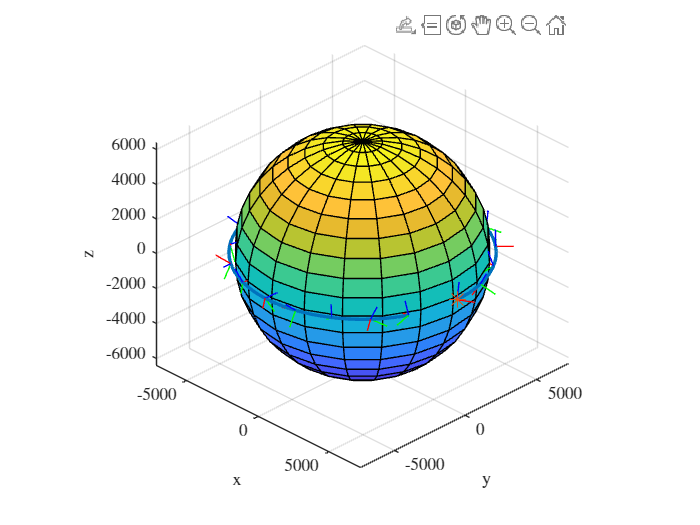

num_att = 20;
k = 1:floor(length(sat1.time)/num_att):length(sat1.time);
atx = zeros(3,length(k));
aty = zeros(3,length(k));
atz = zeros(3,length(k));
for i = k 
    C = EPtoDCM([sat1.q1(i);sat1.q2(i);sat1.q3(i);sat1.q4(i)])*1000;
    atx(:,i) = C*[1;0;0];
    aty(:,i) = C*[0;1;0];
    atz(:,i) = C*[0;0;1];
end

figure()
[xs,ys,zs] = sphere();
plot3(sat1.x,sat1.y,sat1.z,LineWidth=2)
hold on
load('aeroegm2008.mat')
surf(xs*Re/1000,ys*Re/1000,zs*Re/1000)
axis square
axis equal
grid on
for i = k
    quiver3(sat1.x(i),sat1.y(i),sat1.z(i),atx(1,i),atx(2,i),atx(3,i),Color='red')
    quiver3(sat1.x(i),sat1.y(i),sat1.z(i),aty(1,i),aty(2,i),aty(3,i),Color='green')
    quiver3(sat1.x(i),sat1.y(i),sat1.z(i),atz(1,i),atz(2,i),atz(3,i),Color='blue')
end
plot3(sat1.x(1),sat1.y(1),sat1.z(1),'*',MarkerSize=10)
xlabel('x'); ylabel('y'); zlabel('z')
view([45,30])
hold off

function C = EPtoDCM(e)
    C = [1-2*e(2)^2-2*e(3)^2, 2*(e(1)*e(2)+e(3)*e(4)), 2*(e(1)*e(3)-e(2)*e(4));
         2*(e(1)*e(2)-e(3)*e(4)), 1-2*e(1)^2-2*e(3)^2, 2*(e(2)*e(3)+e(1)*e(4));
         2*(e(1)*e(3)+e(2)*e(4)), 2*(e(2)*e(3)-e(1)*e(4)), 1-2*e(1)^2-2*e(2)^2];
end